# Problema 2 - Practic

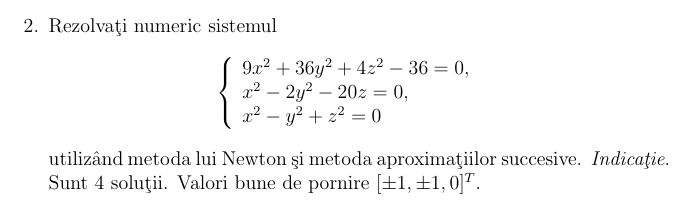

%PB23
function [x, n] = newton_sistem(f, J, x0, epsilon, Nmax)
    % inspirata din Lab12 Metoda lui Newton(pg5)
    x = x0;
    for n = 1:Nmax
        dx = -J(x)\f(x);     % rezolvam: J(x) * dx = -f(x)
        x = x + dx;          % x^{(n+1)} = x^{(n)} + dx
        if norm(dx) < epsilon
            return           % convergenta
        end
    end
    error('Precizia nu a fost atinsa in %d pasi', Nmax);
end
function [x, n] = aprox_succesive_sistem(f, J, x0, epsilon, Nmax)
 % inspirata din Lab12 aproximatiilor succesive(pg5)

    Lambda = -inv(J(x0));     % Lambda fixa, calculata la inceput
    x = x0;
    for n = 1:Nmax
        x_nou = x + Lambda * f(x);   % x_{n+1} = x + Lambda*f(x)
        if norm(x_nou - x) < epsilon
            x = x_nou;
            return
        end
        x = x_nou;
    end
    error('Precizia nu a fost atinsa in %d pasi', Nmax);
end

syms x y z
f_sym = [
    9*x^2 + 36*y^2 + 4*z^2 - 36;
    x^2 - 2*y^2 - 20*z;
    x^2 - y^2 + z^2
];
J_sym = jacobian(f_sym, [x y z]);

f = matlabFunction(f_sym, 'Vars', {[x; y; z]});
J = matlabFunction(J_sym, 'Vars', {[x; y; z]});

epsilon = 1e-10;
Nmax = 50;

x0_list = [
     1,  1, 0;
    -1,  1, 0;
     1, -1, 0;
    -1, -1, 0
]';

fprintf("Sistemul rezolvat este:\n");

Sistemul rezolvat este:


fprintf("   f1(x, y, z) =  9x² + 36y² + 4z² - 36 = 0\n");

   f1(x, y, z) =  9x² + 36y² + 4z² - 36 = 0


fprintf("   f2(x, y, z) =  x² - 2y² - 20z        = 0\n");

   f2(x, y, z) =  x² - 2y² - 20z        = 0


fprintf("   f3(x, y, z) =  x² - y² + z²          = 0\n\n");

   f3(x, y, z) =  x² - y² + z²          = 0



fprintf("Toleranță: ε = %.1e | Numar maxim de iteratii: %d\n", epsilon, Nmax);

Toleranță: ε = 1.0e-10 | Numar maxim de iteratii: 50


fprintf("--------------------------------------------------------------\n\n");

--------------------------------------------------------------




for i = 1:size(x0_list, 2)
    x0 = x0_list(:, i);
    
    fprintf("PUNCT INIȚIAL %d: [x₀, y₀, z₀] = [%.1f, %.1f, %.1f]\n", i, x0(1), x0(2), x0(3));
    fprintf("--------------------------------------------------------------\n");

    % Metoda Newton
    [xn, n1] = newton_sistem(f, J, x0, epsilon, Nmax);
    fprintf("METODA NEWTON:\n");
    fprintf("   x = %.10f\n", xn(1));
    fprintf("   y = %.10f\n", xn(2));
    fprintf("   z = %.10f\n", xn(3));
    fprintf("   Iterații: %d\n", n1);
    fprintf("   Reziduu:  ||f(x)|| = %.2e\n\n", norm(f(xn)));

    % Aproximații succesive
    [xa, n2] = aprox_succesive_sistem(f, J, x0, epsilon, Nmax);
    fprintf("APROXIMATII SUCCESIVE:\n");
    fprintf("   x = %.10f\n", xa(1));
    fprintf("   y = %.10f\n", xa(2));
    fprintf("   z = %.10f\n", xa(3));
    fprintf("   Iterații: %d\n", n2);
    fprintf("   Reziduu:  ||f(x)|| = %.2e\n", norm(f(xa)));
    
    fprintf("==============================================================\n\n");
end

PUNCT INIȚIAL 1: [x₀, y₀, z₀] = [1.0, 1.0, 0.0]


--------------------------------------------------------------


METODA NEWTON:


   x = 0.8936282345


   y = 0.8945270104


   z = -0.0400892862


   Iterații: 5


   Reziduu:  ||f(x)|| = 5.70e-17



APROXIMATII SUCCESIVE:


   x = 0.8936282345


   y = 0.8945270104


   z = -0.0400892862


   Iterații: 11


   Reziduu:  ||f(x)|| = 7.68e-11


PUNCT INIȚIAL 2: [x₀, y₀, z₀] = [-1.0, 1.0, 0.0]


--------------------------------------------------------------


METODA NEWTON:


   x = -0.8936282345


   y = 0.8945270104


   z = -0.0400892862


   Iterații: 5


   Reziduu:  ||f(x)|| = 5.70e-17



APROXIMATII SUCCESIVE:


   x = -0.8936282345


   y = 0.8945270104


   z = -0.0400892862


   Iterații: 11


   Reziduu:  ||f(x)|| = 7.68e-11


PUNCT INIȚIAL 3: [x₀, y₀, z₀] = [1.0, -1.0, 0.0]


--------------------------------------------------------------


METODA NEWTON:


   x = 0.8936282345


   y = -0.8945270104


   z = -0.0400892862


   Iterații: 5


   Reziduu:  ||f(x)|| = 5.70e-17



APROXIMATII SUCCESIVE:


   x = 0.8936282345


   y = -0.8945270104


   z = -0.0400892862


   Iterații: 11


   Reziduu:  ||f(x)|| = 7.68e-11


PUNCT INIȚIAL 4: [x₀, y₀, z₀] = [-1.0, -1.0, 0.0]


--------------------------------------------------------------


METODA NEWTON:


   x = -0.8936282345


   y = -0.8945270104


   z = -0.0400892862


   Iterații: 5


   Reziduu:  ||f(x)|| = 5.70e-17



APROXIMATII SUCCESIVE:


   x = -0.8936282345


   y = -0.8945270104


   z = -0.0400892862


   Iterații: 11


   Reziduu:  ||f(x)|| = 7.68e-11
